robot = importrobot('C:\Users\niyu2\MATLAB\CQL_deployment\stretch_urdf-main\stretch_urdf\RE2V0\stretch_description_RE2V0_tool_stretch_gripper.urdf');
showdetails(robot);

--------------------
Robot: (43 bodies)

 Idx                           Body Name                           Joint Name                           Joint Type                           Parent Name(Idx)   Children Name(s)
 ---                           ---------                           ----------                           ----------                           ----------------   ----------------
   1                         caster_link                         caster_joint                                fixed                               base_link(0)   
   2                link_aruco_left_base                joint_aruco_left_base                                fixed                               base_link(0)   
   3               link_aruco_right_base               joint_aruco_right_base                                fixed                               base_link(0)   
   4                            base_imu                       joint_base_imu                                fixed        

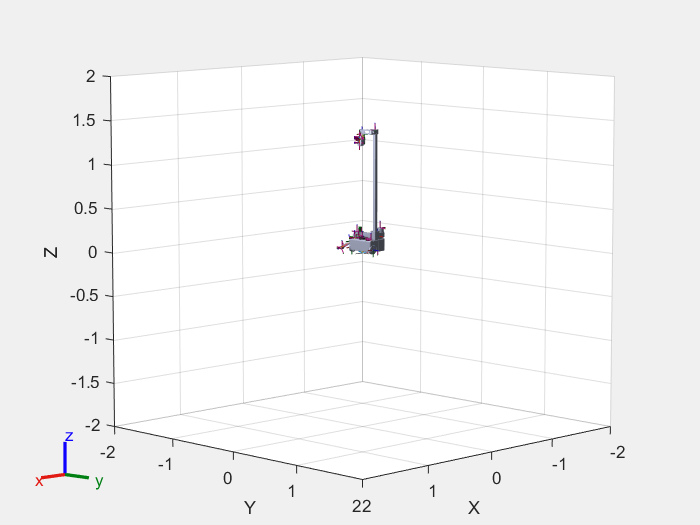

show(robot);

grid_size = [8, 8]

grid_size =      8     8


goal_state = [5,5]

goal_state =      5     5


obstacle_states = [[1, 2], [2, 2], [1, 3]]

obstacle_states =      1     2     2     2     1     3


env = py.QLearning_mach2.GridEnvironment(grid_size, goal_state, obstacle_states);

result = py.QLearning_mach2.learn(env, int32(1));

Run 1: Learned Q-table:
[[-17.42070718  -9.87586955 -17.83498469  -9.87618879]
 [-17.84621251  -9.8700083   -9.86944887  -9.87008071]
 [-17.47144217  -9.86644059  -9.86539456  -9.86597456]
 [-17.06680471  -9.86322347  -9.86404783  -9.86314784]
 [-17.28923029  -9.86125331  -9.86136698  -9.86042715]
 [-16.80269976  -9.85886549  -9.86001686  -9.8586078 ]
 [-16.92555162  -9.85793244  -9.8579081   -9.85705793]
 [-16.74153678  -9.8565726   -9.85759503 -16.98227894]
 [ -9.87077235  -9.87001043 -17.46595041  -9.86927272]
 [ -9.86684732  -9.86696718  -9.86754012  -9.86680493]
 [ -9.86422847  -9.8648757   -9.86479335  -9.86454808]
 [ -9.86294081  -9.86154209  -9.86264203  -9.86177431]
 [ -9.85993668  -9.86121797  -9.86031436  -9.86011121]
 [ -9.8591504   -9.8588991   -9.85880826  -9.85776077]
 [ -9.85698693  -9.85732998  -9.85805523  -9.8574109 ]
 [ -9.85701239  -9.85697082  -9.8575485  -17.55934239]
 [ -9.86542861  -9.86516206 -17.77335992  -9.86620054]
 [ -9.86403691  -9.86415744  -9.86358207 

disp(result);

  Python list with values:

    [[-271, -262, -253, -208, -244, -352, -280, -154, -136, -199, -226, -190, -181, -181, -190, -145, -154, -154, -163, -226, -190, -316, -181, -235, -163, -226, -181, -190, -199, -199, -118, -190, -172, -172, -190, -253, -235, -145, -136, -181, -136, -217, -235, -145, -280, -181, -190, -235, -127, -172, -199, -181, -352, -262, -208, -235, -154, -190, -208, -163, -235, -172, -199, -145, -217, -172, -181, -190, -280, -163, -145, -145, -199, -199, -163, -145, -154, -181, -190, -199, -163, -172, -154, -181, -244, -172, -154, -163, -199, -163, -172, -181, -262, -154, -181, -127, -172, -127, -145, -154, -145, -118, -127, -100, -154, -172, -163, -163, -109, -199, -181, -190, -154, -190, -136, -136, -199, -190, -154, -181, -163, -136, -235, -154, -145, -208, -118, -163, -136, -190, -118, -154, -145, -127, -154, -136, -172, -145, -145, -118, -136, -118, -118, -127, -181, -172, -172, -190, -136, -127,

save('policy_input.mat', 'result');

agent = py.QLearning_mach2.QLearning(env);

robot_ip = "http://10.206.90.31:11311";
rosinit(robot_ip);

Cannot connect to ROS master at http://10.206.90.31:11311. Check the specified address or hostname.